clear all
clc
fs = 1000;%采样频率
f = 200;
f2 = 400;
Ts = 1/fs;
t = Ts:Ts:2;%总共2s长的信号
Nfft = 2000;%与这里信号相同，导致时域信号是连续的，如果这个值变大，则出现泄露
y= cos(2*pi*f*t)+cos(2*pi*f2*t)

y =    -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000


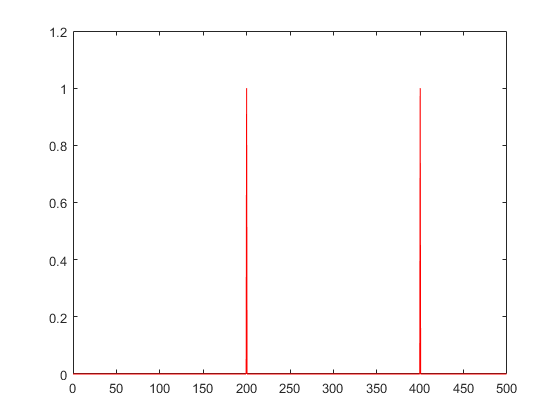

py = fft(y,Nfft);
f_label = 0 :fs/Nfft:fs/2-fs/Nfft;
amp = abs(py);
amp = amp(1:Nfft/2)/(Nfft/2);
plot(f_label,amp,"r")

%这里可以明显看出DFT的一种近似特性，对于周期信号，如果重复的不是完整周期，则出现失真

% clear all
% clc
fs = 1000;%采样频率
f = 200;
f2 = 400;
Ts = 1/fs;
t = Ts:Ts:2;%总共2s长的信号
Nfft = 2000;%与这里信号相同，导致时域信号是连续的，如果这个值变大，则出现泄露
y= cos(2*pi*f*t)+cos(2*pi*f2*t)

y =    -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000   -0.5000   -0.5000   -0.5000   -0.5000    2.0000


py = fft(y,Nfft);
f_label = 0 :fs/Nfft:fs/2-fs/Nfft;
amp = abs(py);
amp = amp(1:Nfft/2)/(Nfft/2);
plot(f_label,amp,"r")

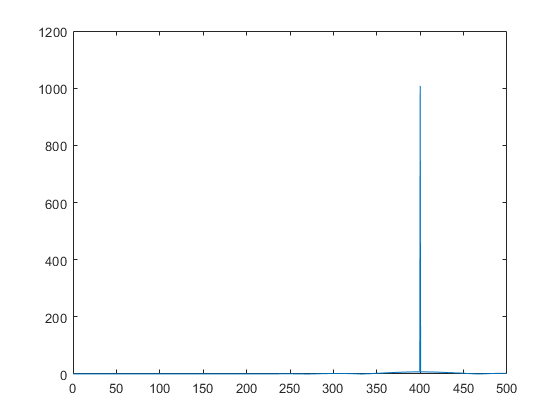

%在这里我们使用matlab的filter_designer对信号进行一个滤波的显示
y_after_filtered = filter(filter1,1,y);%这里代表用b a 对应的系数进行滤波
%运行这段程序时，需要利用filterDesigner进行设计，将系数导出到工作区
py_after_filtered = abs(fft(y_after_filtered,Nfft));
py_after_filtered = py_after_filtered(1:Nfft/2);
figure(2)
plot(f_label,py_after_filtered)